# Calling Python from MATLAB

### This document is a Live Script

This document is an example of a MATLAB Live Script.  Live scripts represent MathWorks' vision of the Notebook paradigm and are very tightly integrated with the MATLAB ecosytem.  While there are some differences between Live Scripts and Jupyter notebooks, there are also many similarities.  Indeed, in R2023b it will be possible to convert Live Scripts to Jupyter Notebooks!  For more details on Live Scripts, refer to [What Is a Live Script or Function? - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html)

### **We have some Python code and want to run it in Python**

A collaborator has given us some Python code, `weather.py`, that imports current weather data from the web. We want to make use of it from within MATLAB.

First things first, let's check that MATLAB is cofigured with Python correctly

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "/usr/local/python/current/bin/python3"
          Library: "libpython3.10.so.1.0"
             Home: "/usr"
           Status: NotLoaded
    ExecutionMode: InProcess


We can take a quick look at weather.py inside this live script which simply displays any text file

type weather.py

# -*- coding: utf-8 -*-
'''
Created on Thu Jan  4 20:41:45 2018
Modified Jan 29 2019
Simplified June 16 2022

'''

# weather.py
import datetime
import json  
import urllib.request

BASE_URL = '/data/2.5/{}?q={},{}&appid={}'

def get_current_weather(city, country, apikey,**kwargs):  
    '''get current conditions in specified location
    appid='b1b15e88fa797225412429c1c50c122a1'
    get_current_weather('London','uk',appid,api='samples')'''

    # select between samples or prod api
    if 'api' in kwargs:
        if kwargs['api'] == 'samples':
            DOMAIN = "http://samples.openweathermap.org"
        else:
            print('not the right api arg')
            DOMAIN = "http://api.openweathermap.org"
    else:
        DOMAIN = "http://api.openweathermap.org"

    # Read current conditions
    try:
        # url = 'http://samples.openweathermap.org/data/2.5/weather?q=London,uk&appid=b1b15e88fa797225412429c1c50c122a1'
        url = DOMAIN + BASE_URL.format('weather',city,country,ap

For a fuller featured experience, open in MATLAB editor

edit weather.py

This investigation shows us that we can run weather.py as a script!  The easiest way to do that inside MATLAB is with the `pyrunfile` command

pyrunfile("weather.py")

Running weather.py as a script
Getting current weather for London
{'coord': {'lon': -0.13, 'lat': 51.51}, 'weather': [{'id': 300, 'main': 'Drizzle', 'description': 'light intensity drizzle', 'icon': '09d'}], 'base': 'stations', 'main': {'temp': 280.32, 'pressure': 1012, 'humidity': 81, 'temp_min': 279.15, 'temp_max': 281.15}, 'visibility': 10000, 'wind': {'speed': 4.1, 'deg': 80}, 'clouds': {'all': 90}, 'dt': 1485789600, 'sys': {'type': 1, 'id': 5091, 'message': 0.0103, 'country': 'GB', 'sunrise': 1485762037, 'sunset': 1485794875}, 'id': 2643743, 'name': 'London', 'cod': 200}


The problem with this approach is that nothing is returned back to MATLAB that we can use in subsequent calcuations.  In some cases, this is fine.  For example, perhaps your Python script produces a file that we can later load into MATLAB. 

In this case, however, we need to use a different approach and call the Python functions directly from MATLAB. 

**Calling Python functions from MATLAB**

Just add `py.` to call functions from Python.  Here's how to call the `sqrt `function from Python's `math` module. 

py.math.sqrt(42)

ans = 6.4807

Calling a numpy function is just as easy. Let's first generate a 3x3 magic square in MATLAB

a=magic(3)

a =      8     1     6
     3     5     7
     4     9     2


and compute the QR decomposition in numpy

pyQR = py.numpy.linalg.qr(a)

pyQR =   Python QRResult with properties:

    Q
    R

    QRResult(Q=array([[-0.8479983 ,  0.52229204,  0.09005497],
           [-0.31799936, -0.36546806, -0.8748197 ],
           [-0.42399915, -0.77048304,  0.47600483]]), R=array([[-9.43398113, -6.25398749, -8.16198368],
           [ 0.        , -8.23939564, -0.96549025],
           [ 0.        ,  0.        , -4.63139839]]))


A little extra work is required to get the individual matrices from that result

pyQ = pyQR.Q

pyQ =   Python ndarray:

   -0.8480    0.5223    0.0901
   -0.3180   -0.3655   -0.8748
   -0.4240   -0.7705    0.4760

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


pyR = pyQR.R

pyR =   Python ndarray:

   -9.4340   -6.2540   -8.1620
         0   -8.2394   -0.9655
         0         0   -4.6314

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


You can see that its easy to use whatever Python functions you have installed from within MATLAB.  

Let's now use MATLAB's `qr` function to directly as a comparison

[Q,R] = qr(a)

Q =    -0.8480    0.5223    0.0901
   -0.3180   -0.3655   -0.8748
   -0.4240   -0.7705    0.4760


R =    -9.4340   -6.2540   -8.1620
         0   -8.2394   -0.9655
         0         0   -4.6314


Use MATLAB `name=value` syntax for Python named arguments.

hw = py.textwrap.wrap("Hello world!", width = 2)

This failed because python is often more strict than MATLAB about data types. 

hw = py.textwrap.wrap("Hello world!", width = int32(2))

hw =   Python list with values:

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

    Use string, double or cell function to convert to a MATLAB array.


Convert to appropriate MATLAB type, if desired.

hw = string(hw)

hw = 1x6 string array
    "He"    "ll"    "o "    "wo"    "rl"    "d!"


## Read weather data using Python module 

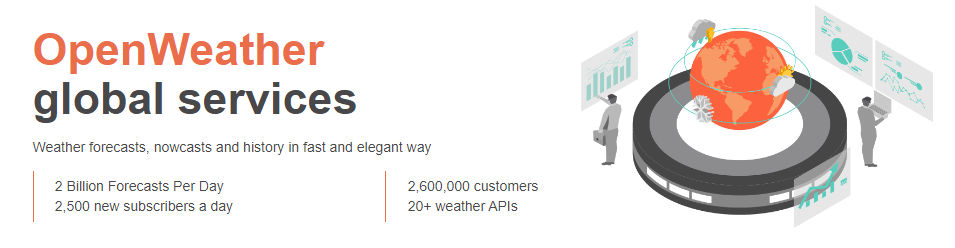

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

% apikey = readtable("accessKey.txt","TextType","string"); 

Or use the sample API key

appid ='b1b15e88fa797225412429c1c50c122a1';

Use the weather.py module to get the air quality for London. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("London","UK",appid,api='samples')

jsonData =   Python dict with no properties.

    {'coord': {'lon': -0.13, 'lat': 51.51}, 'weather': [{'id': 300, 'main': 'Drizzle', 'description': 'light intensity drizzle', 'icon': '09d'}], 'base': 'stations', 'main': {'temp': 280.32, 'pressure': 1012, 'humidity': 81, 'temp_min': 279.15, 'temp_max': 281.15}, 'visibility': 10000, 'wind': {'speed': 4.1, 'deg': 80}, 'clouds': {'all': 90}, 'dt': 1485789600, 'sys': {'type': 1, 'id': 5091, 'message': 0.0103, 'country': 'GB', 'sunrise': 1485762037, 'sunset': 1485794875}, 'id': 2643743, 'name': 'London', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 280.32, 'pressure': 1012, 'humidity': 81, 'temp_min': 279.15, 'temp_max': 281.15, 'speed': 4.1, 'deg': 80, 'lon': -0.13, 'lat': 51.51, 'city': 'London', 'current_time': '2024-08-16 15:30:58.127398'}


## Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 280.3200
        pressure: [1x1 py.int]
        humidity: [1x1 py.int]
        temp_min: 279.1500
        temp_max: 281.1500
           speed: 4.1000
             deg: [1x1 py.int]
             lon: -0.1300
             lat: 51.5100
            city: [1x6 py.str]
    current_time: [1x26 py.str]


Convert the remaining python types to the desired MATLAB data types.

string(data.city)

ans = "London"

Perform the remaining conversions using the custom `convertData` function (see the end of this Script)

convertData(data)

ans = 1x9 table
      T        P      RH    WindSpd    WindDir     lon      lat       city           DateLocal      
    ______    ____    __    _______    _______    _____    _____    ________    ____________________

    280.32    1012    81      4.1        80       -0.13    51.51    "London"    16-Aug-2024 15:30:58


## Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Munich.

jsonData = py.weather.get_forecast('Muenchen','DE',appid,api='samples');
forecastData = py.weather.parse_forecast_json(jsonData);  
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1x36 py.list]
            temp: [1x36 py.list]
             deg: [1x36 py.list]
           speed: [1x36 py.list]
        humidity: [1x36 py.list]
        pressure: [1x36 py.list]


The type of data returned by the parsed forecast date is a **Python array**:

forecast.temp

ans =   Python list with values:

    [286.67, 285.66, 277.05, 272.78, 273.341, 275.568, 276.478, 276.67, 278.253, 276.455, 275.639, 275.459, 275.035, 274.965, 274.562, 275.648, 277.927, 278.367, 273.797, 271.239, 269.553, 268.198, 267.295, 272.956, 277.422, 277.984, 272.459, 269.473, 268.793, 268.106, 267.655, 273.75, 279.302, 279.343, 274.443, 272.424]

    Use string, double or cell function to convert to a MATLAB array.


Convert to a MATLAB double array (and from Kelvin to Celsius)

temp = double(forecast.temp) - 273.15

temp =    13.5200   12.5100    3.9000   -0.3700    0.1910    2.4180    3.3280    3.5200    5.1030    3.3050    2.4890    2.3090    1.8850    1.8150    1.4120    2.4980    4.7770    5.2170    0.6470   -1.9110   -3.5970   -4.9520   -5.8550   -0.1940    4.2720    4.8340   -0.6910   -3.6770   -4.3570   -5.0440   -5.4950    0.6000    6.1520    6.1930    1.2930   -0.7260


Current time is a list of strings.

forecast.current_time

ans =   Python list with values:

    ['2017-02-16 12:00:00', '2017-02-16 15:00:00', '2017-02-16 18:00:00', '2017-02-16 21:00:00', '2017-02-17 00:00:00', '2017-02-17 03:00:00', '2017-02-17 06:00:00', '2017-02-17 09:00:00', '2017-02-17 12:00:00', '2017-02-17 15:00:00', '2017-02-17 18:00:00', '2017-02-17 21:00:00', '2017-02-18 00:00:00', '2017-02-18 03:00:00', '2017-02-18 06:00:00', '2017-02-18 09:00:00', '2017-02-18 12:00:00', '2017-02-18 15:00:00', '2017-02-18 18:00:00', '2017-02-18 21:00:00', '2017-02-19 00:00:00', '2017-02-19 03:00:00', '2017-02-19 06:00:00', '2017-02-19 09:00:00', '2017-02-19 12:00:00', '2017-02-19 15:00:00', '2017-02-19 18:00:00', '2017-02-19 21:00:00', '2017-02-20 00:00:00', '2017-02-20 03:00:00', '2017-02-20 06:00:00', '2017-02-20 09:00:00', '2017-02-20 12:00:00', '2017-02-20 15:00:00', '2017-02-20 18:00:00', '2017-02-20 21:00:00']

    Use string, double or cell function to convert to a MATLAB ar

Convert to a MATLAB string, and then to a MATLAB datetime:

time = datetime(string(forecast.current_time))

time = 1x36 datetime array
   16-Feb-2017 12:00:00   16-Feb-2017 15:00:00   16-Feb-2017 18:00:00   16-Feb-2017 21:00:00   17-Feb-2017 00:00:00   17-Feb-2017 03:00:00   17-Feb-2017 06:00:00   17-Feb-2017 09:00:00   17-Feb-2017 12:00:00   17-Feb-2017 15:00:00   17-Feb-2017 18:00:00   17-Feb-2017 21:00:00   18-Feb-2017 00:00:00   18-Feb-2017 03:00:00   18-Feb-2017 06:00:00   18-Feb-2017 09:00:00   18-Feb-2017 12:00:00   18-Feb-2017 15:00:00   18-Feb-2017 18:00:00   18-Feb-2017 21:00:00   19-Feb-2017 00:00:00   19-Feb-2017 03:00:00   19-Feb-2017 06:00:00   19-Feb-2017 09:00:00   19-Feb-2017 12:00:00   19-Feb-2017 15:00:00   19-Feb-2017 18:00:00   19-Feb-2017 21:00:00   20-Feb-2017 00:00:00   20-Feb-2017 03:00:00   20-Feb-2017 06:00:00   20-Feb-2017 09:00:00   20-Feb-2017 12:00:00   20-Feb-2017 15:00:00   20-Feb-2017 18:00:00   20-Feb-2017 21:00:00


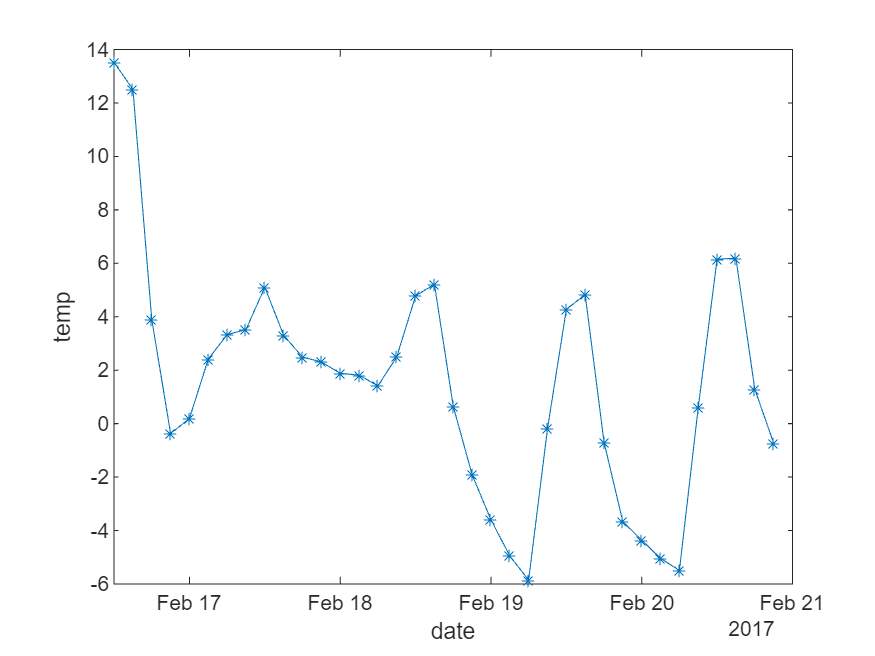

plot(time,temp,'-*')
xlabel("date")
ylabel("temp")

## Retime and smooth data using Live Editor Tasks

Weather forecasts are only provided every 3 hours. We want to retime to have data interpolated every single hour.

T = timetable(time',temp','VariableNames',{'Temperature'})

T = 36x1 timetable
            Time            Temperature
    ____________________    ___________

    16-Feb-2017 12:00:00       13.52   
    16-Feb-2017 15:00:00       12.51   
    16-Feb-2017 18:00:00         3.9   
    16-Feb-2017 21:00:00       -0.37   
    17-Feb-2017 00:00:00       0.191   
    17-Feb-2017 03:00:00       2.418   
    17-Feb-2017 06:00:00       3.328   
    17-Feb-2017 09:00:00        3.52   
    17-Feb-2017 12:00:00       5.103   
    17-Feb-2017 15:00:00       3.305   
    17-Feb-2017 18:00:00       2.489   
    17-Feb-2017 21:00:00       2.309   
    18-Feb-2017 00:00:00       1.885   
    18-Feb-2017 03:00:00       1.815   
    18-Feb-2017 06:00:00</

% Use Retime livescript here. Every hour. Linear interpolation


% Use smooth data here. Moving mean smoothing method. Smoothing factor 0.25

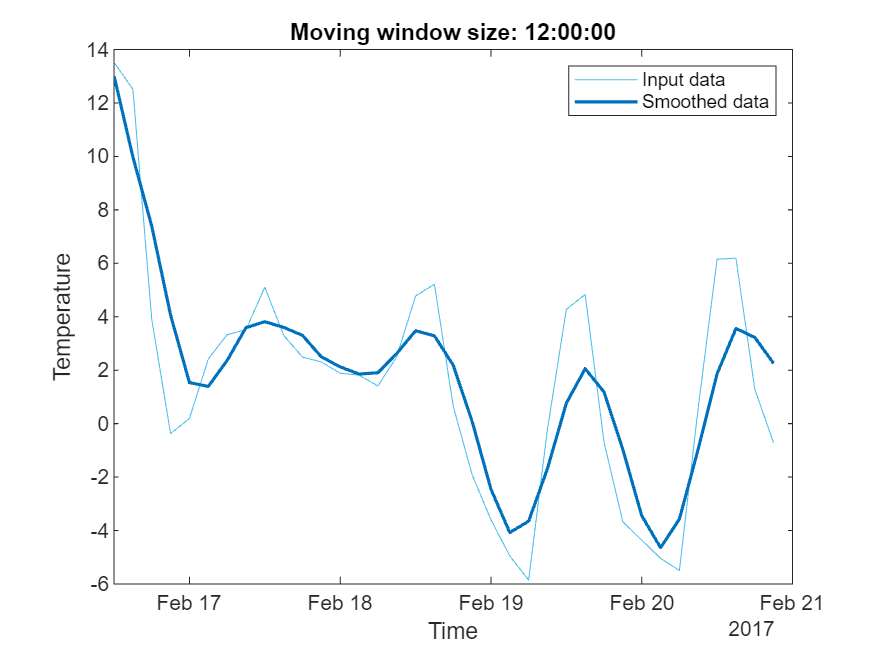

% Smooth input data
[newTable,winSize2] = smoothdata(T,"movmean","SmoothingFactor",0.25);

% Display results
figure
plot(T.Time,T.Temperature,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(T.Time,newTable.Temperature,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize2));
legend
ylabel("Temperature")
xlabel("Time")

clear winSize2

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

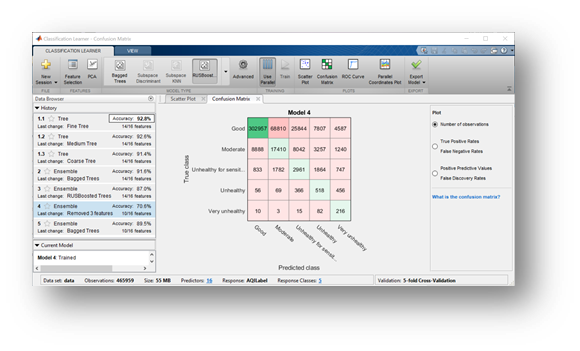

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

currentData = 1x12 table
         DateLocal            city      StateName     T       P        DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _________    ____    ____    ______    __    _______    _______    ____    __    __

    16-Aug-2024 15:30:58    "London"       UK        7.17    1012    273.48    81      80         4.1      2024    8     16


Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' contains a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel model

airQual = predict(model,currentData)

airQual = categorical
     Good 


**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end